# GReS - Sedimentation model

## Introduction

This tutorial describes how to use the sedimentation module currently available in GReS. In its current implementation, the module is designed to operate as a standalone feature and does not support coupling with other physics. This limitation is by design. Consequently, some GReS functionalities described in other tutorials have additional restrictions or behave slightly differently when used with the sedimentation module, as they have been adapted and optimized to support its current implementation.

cd(fullfile(gres_root,'Tutorial','sedimentation'))
sedimentation_root = fullfile(gres_root,'Tests','Sedimentation','LinearSedimentation2D');

## Governing equations

The governing equation system controlling the grow and compaction of a sedimentation basin undergoing large deformations can be written as


$$\begin{cases}
\bigg(c_b+\frac{e}{1+e}\beta\bigg) \frac{\partial p}{\partial t} - \nabla \cdot \bigg( \frac{\mathbf{K}}{\gamma} \nabla  p\bigg) = c_b \dot{\sigma_z} & \text{on}\ \Omega\times I
\\[6pt]

\sigma = \sigma_z - p& \text{on}\ \Omega\times I
\\[6pt]

\dot{\sigma_z} = \frac{\gamma_s-\gamma}{1+e_0}\omega  & \text{on}\ \Omega\times I
\end{cases}$$
   

where:

- $c_b$ is the oedometric soil compressibility;

- $\mathbf{K}$ is the hydraulic conductivity tensor;

- $ \gamma$ is the specific weight of the water;

- $ \gamma_s$ is the specific weight of the solid being sedimentation;

- $ \beta$ is the volumetric compressibility of water;

- $\sigma$ is the vertical total stress;

- $\sigma_z$ is the vertical effective stress;

- $p$ is the over pressure field;

- $e$ is the void rate.

- $e_0$ is the initial void rate.

- $\omega$ is the sedimentation rate.

- $\Omega$ is the domain, and can be idealized as in the figure

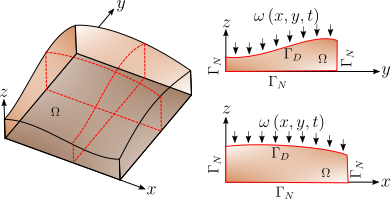

The boundary conditions for this system, are prescribed as


$$\begin{cases}
    p(\mathbf{x},t) = 0 
    & \text{on } \,  \Gamma_D\\[6pt]

     -\frac{\mathbf{K}}{\gamma} \nabla  p \cdot \mathbf{n} = 0
    & \text{on } \, \Gamma_N
\end{cases}
$$


Which is a zero over pressure surface at the top of the domain, and a no flow condition for the rest of the boundary. The initial condition is always set to be the hydrostatic pressure.

In this module, Terzaghi's principle is applied under the assumption that deformation is restricted to a one-dimensional soil column along the z-axis. The adopted constitutive model also assumes that the soil grains themselves do not deform. Consequently, all volumetric deformation is attributed to changes in the volume of the void spaces between the soil particles, simplified to be changes only in the z direction.

The constitutive relationships are defined for two stress regimes: (1) when the effective stress is below the pre consolidation stress, and (2) when it exceeds the pre consolidation stress. This is express in incremental form, and these relationships link the variation of void ratio ($\delta e$) to the effective stress ($\sigma_*$) levels through the re compression index ($C_r$) and the compression index ($C_c$).

The deformation is also written in a incremental form as:


$$\epsilon_{curr} = \epsilon_{prev} + \delta\epsilon$$


so the vertical compaction in the Lagrangian case is computed as


$$u(\xi,t) = \int_{0}^{\xi}\epsilon d\xi \rightarrow u_{curr} = H_0 \epsilon_{curr}$$


where $H_0$ is the initial thickness of a cell.

The $c_b$ is related to the compressibility index $C_c$ provided by the usual graphical interpretation of oedometric tests through the

relationship


$$c_b = \frac{1}{\ln10}\frac{C_c}{(1+e)\sigma_z}$$


## Problem setting

The numerical experiment reproduces the basin evolution described by Teatini, 2022 and Zoccarato, 2017.  The model simulates basin formation through three distinct sedimentation periods on a basin with a base measuring **10 × 3 m²**. The figure illustrates a schematic of the computational domain at the beginning of each sedimentation period, together with the expected domain configuration at the end of the simulation.

During the peat and clay deposition periods, sediments are deposited at a constant rate of **3 mm/year**, which is uniform in both time and space. In the final period, corresponding to silt deposition, the sedimentation rate remains constant in time but varies linearly along the **x**-direction, ranging from **0 to 3 mm/year**. As a result, the simulation produces a three-layer sedimentary basin, as illustrated in the final panel of the figure.

## Preprocessor Phase - Model setup

### Materials

To define the materials in the simulation, you create a new instance of the `Materials` class. This object takes a file containing the material values as input.

mat = Materials(fullfile(sedimentation_root,'Input','materials.xml'));

**The user is responsible for the dimensional consistency of all physical quantities involved in the model.**

we need an input file file containing the list of the materials

**.xml File Format** -> materials.xml

For this module, the `cellTags` attribute in the `<Solid>` block has a different meaning. Every cell in the computational domain is represented as a mixture of all defined solid materials. Instead of identifying a region of the domain, `cellTags` specifies the material identifier associated with each `<Solid>` block. The composition of each cell is then defined by the normalized volume fraction of each material (`cellTags`). **The assigned value must be an integer less than or equal to the total number of **`<Solid>`** blocks, not being necessary to be ordered.**

The **fluid** is always defined for the **entire domain**, thus requiring only **one block** with its properties. **If more the one block are specified for a fluid material, GReS will throw an error.**  This block `holds` the specific weight of the fluid (here assumed to be 0 to neglect gravitational effects), the fluid compressibility, and the dynamic viscosity.

**Fluid Block** 

For this module, the two fluid properties that must be specified are the `specificWeight`($ \gamma$) and the `compressibility`($ \beta$).

**Solid Block** 

Inside the `<Solid>` block, all the proprieties for this physics is define inside the `<Constitutive> law` block. Within this block, the material model for the sedimentation module is specified using the `<SedimentMaterial>`.

Initial void rate values $e_0$ must be specified for the materials deposited within the domain. However, these parameters are typically obtained in laboratory tests performed under stress conditions that differ from those present in the simulation.

The material properties required are:

- `specificWeight` ($ \gamma_s$) - the specific weight of the solid material.

- `conductivity` ($\mathbf{K}$) - the hydraulic conductivity tensor. By construction, the tensor is assumed to be isotropic, with independent values defined along the x, y, and z directions.

- `voidRatio` ($e_0$) - the laboratory-measured initial void ratio.

- `voidLowerLimit` - the minimum allowable void ratio for this material.

- `voidUpperLimit` - the maximum allowable void ratio for this material.

- `compressibilityIndex` ($C_c$) - the compressibility index of the material.

- `reCompressibilityIndex` ($C_r$) -  the re compressibility index of the material.

- `initStress` ($\sigma_0$) - the stress level corresponding to the laboratory-measured void ratio.

- `preStress` ($\sigma_{p}$) -  the preconsolidation stress of the material.

### Discretizer

We instantiate the Discretizer class to create a domain object. This class acts as a wrapper, storing a database of the model's physical solvers in its solver property. It also includes a State property, which is an object that holds the primary variables and derived quantities of the model for a specific point in time.

domain = Discretizer('Materials',mat);

### Setting the physics

This step establishes the physical laws and principles that govern the behavior of the simulation. The active physical models are defined by the command

domain.addPhysicsSolvers(fullfile(sedimentation_root,'Input','solver.xml'));

we need an input file file containing the this structure for set up of the simulation

**.xml File Format** -> solver.xml

This file is organized into three main blocks: `<Domain>`, which defines the simulation domain and computational grid; `<Boundary>`, which specifies the boundary conditions; and `<SedimentationMap>`, which describes the amount of sediment deposited on the top cells of the domain throughout the simulation. Each block is explained in detail in the following sections.

#### Domain

Unlike the workflow described in the [grid tutorial](matlab:open('../grid/grid.mlx')) and other GReS tutorials, **you should not create an initial computational domain** using the `Grid` class. Instead, create the discretization without providing a grid. Internally, GReS initializes an empty grid, which is later configured automatically when the sedimentation physics is added. At that stage, the sedimentation module initializes the computational domain according to the specifications provided in the solver input file.

**In the current version of this module, the computational domain always starts as a flat plane and evolves according to the applied sedimentation map**. It is recommended to define the initial configuration as a rigid, highly permeable foundation. Because this material neither deforms nor develops excess pore pressure, it does not affect the simulation results and may be removed during post-processing to simplify the visualization. If a flat plane does not adequately represent the bathymetry of the region of interest, the desired initial geometry can be generated by adding an initial deposition stage using the same foundation material to construct the desired initial configuration.

The `<Domain>` field is composed of three blocks:

`<Grid>`

Defines the number of cells along each axis and the nodal coordinates that define the grid. Two constructors are available:

This constructor builds a structured mesh for a parallelepiped  domain with dimensions 10×10×1 and a grid resolution of 3×3×2 cells.

This constructor builds a mesh by explicitly providing the coordinates along each axis. Coordinates can be defined either directly as a list of values using "*coord" or read from a file using "*file". **If both "*file" and "*coord" are defined for the same axis, the "*coord" definition is ignored.**

`<Initial>`

Defines which cells from the Grid compose the initial simulation domain. 

The field "`type`" must be specified to determine how the initial configuration is built. Available options are:

- `all`: All possible cells defined in Grid are active.

- `surface` (experimental): The initial domain represent a defined surface.

For the surface option an additional field defining the surface map will be required.

It is also mandatory to define the material composition of the active cells, either by:

- `materialTag`: all active cells are composed of equal proportions of the listed materials.

- `materialFractions`: explicit material fractions are provided for each cell.

`<NewCellHeightControl>`

This field control the height of the cell create at in the evolving process, 

When the cell at the top of the domain reaches this value, the growing cell is converted into a regular cell, and a new growing cell is created above it. As a result, the thickness of cells within the sedimentary domain never exceeds this value, except for the cells belonging to the initial configuration (the flat-plane).

#### Boundary condition

Similar to the computational domain, **boundary conditions should not be explicitly created using the **`Boundary`** class**. Instead, they are managed internally by the sedimentation module. GReS initializes an empty boundary object, which is automatically configured when the sedimentation physics is added. At that stage, the module defines the required boundary conditions according to the specifications provided in the solver input file.

Within the `<Boundary>` block, each `<BC>` entry defines a boundary condition.

The general form is:

Where:

- `surface`: domain boundary where the condition is applied(xmin, xmax, ymin, ymax, zmin, zmax).

- `type`: boundary condition type (Dirichlet or Neumann).

- `value`: prescribed boundary value.

#### Sedimentation map

The `<SedimentMap>` field point to the file that defines the spatial and temporal distribution of sediment deposition on the top of the domain. This new file is constructed as follows:

The `<Sedimentation_Maps type = XXX>` block is used to define the spatial and temporal distribution of sediment deposition rates within the simulation domain. The spatial distribution of sedimentation is applied exclusively to the top surface of the domain and is specified through `<Event>` blocks. The required attribute "`type`" defines the temporal behavior of sedimentation between consecutive events.

Allowed values for "type":

- `ramp` : Each `<Event>` block defines a new sedimentation map. The map remains unchanged until the next event occurs. In this mode, the deposition rate may vary spatially, but remains constant in time between two consecutive events.

- `linear` : Between two consecutive `<Event>` blocks, referred to as event A and event B, the sedimentation map evolves linearly in time. The deposition rate values are interpolated between those defined in event A to those specified in event B.

`Each ``<Event time="XXX">` block defines a new sedimentation map applied to the top surface of the domain. Where `time,`associated with the sedimentation map defined by the event. The value must be specified as a real number.

Inside each `<Event time="XXX">``, is allow to use the `child blocks:

These blocks may be used simultaneously and in any combination. However the quantity of this child blocks is limited by the number of solid material.

Defines a uniform sedimentation rate over the entire top surface of the domain for a given material.

Attributes:

- materialFlag - Identifier of the material to which sedimentation is applied. This value must correspond to the cellTags attribute defined in the material declaration:  `<Solid name="XXXX" cellTags="X">`` .`**If no material corresponding to the specified value exists, the block is ignored.**

- value - Uniform sedimentation rate applied throughout the domain for the specified material.

Defines a spatially varying sedimentation rate through bilinear interpolation over the top surface of the domain.

Attributes:

- materialFlag - Identifier of the material to which sedimentation is applied. This value must correspond to the cellTags attribute defined in the material declaration: `<Solid name="XXXX" cellTags="X">`` . `**If no material corresponding to the specified value exists, the block is ignored.**

- value - Set of four values representing the sedimentation rate at the four  corner vertices of the domain top surface. Values must be specified in the following order: value = "v1, v2, v3, v4", where v1, v2, v3, and v4 correspond to the sedimentation rates at vertices 1, 2, 3, and 4, respectively. The vertex numbering convention is:

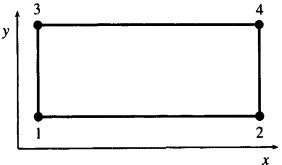

Defines the sedimentation rate on the top surface of the domain from a discrete map of values.

Attributes:

- materialFlag - Identifier of the material to which sedimentation is applied. This value must correspond to the cellTags attribute defined in the material declaration:  `<Solid name="XXXX" cellTags="X">``. `**If no material corresponding to the specified value exists, the block is ignored.**

- division - Number of points used to discretize the sedimentation map along the directions of the domain top surface. If these values match the discretization used by the solver, each sedimentation value is directly assigned to a domain column. Otherwise, a linear interpolation/extrapolation is performed between the input map and the discretization effectively used in the simulation.

- file - Path to the file containing the sedimentation map values. The file must contain exactly NX × NY values, where NX and NY are the dimensions specified by the division attribute.

### Simulation loop

We specify the simulation parameters as described in the other tutorials, by providing a xml file to the `SimulationParameters` object. 

or by the command line

simParam = SimulationParameters('Start',0.,'End',1.0e3,...
      'DtInit',1e-0,'DtMin',1e-2,'DtMax',1e-0,'MaxNLIteration',30);

To finalize the preprocessor phase, you'll control the output details of the simulation by creating an instance of the `OutState` class (more details in the other tutorials).

printUtils = OutState('outputFile','Outputs/Results','printTimes',0:25:1000);

## Processor Phase - Solution

We are now ready to set up the solver:

solver = EvolvingGrid('simulationparameters',simParam,...
                      'domains',domain,...
                      'output',printUtils, ...
                      'growprint',0, ...
                      'intervalprint',[0,400]);

The sedimentation module uses a dedicated solution scheme called `EvolvingGrid`, which was introduced in the *First Steps* tutorial. Its structure is similar to the standard solution scheme and requires the following components:

- discretization settings,

- nonlinear solver parameters, and

- output configuration.

In addition, `EvolvingGrid` includes two optional output-control parameters: `growprint` and `intervalprint`. These parameters modify the default output behavior by generating additional results in both the VTK visualization files and the `printUtils.result` structure. In most applications, however, it's recommend to avoid use them.

The `growprint` parameter controls whether the solution is saved immediately after new cells are created. By default (`growprint = 0`), the output configuration is unchanged. If `growprint` is set to a nonzero value, an additional output is generated at the first time step after each grid growth event.

The `intervalprint` parameter overrides the standard output configuration by saving the solution at every time step within a user-defined time interval. This option is useful when a higher temporal resolution is needed during a specific stage of the simulation, but it produce a large number of output files and substantially increase storage requirements.

The actual simulation—namely, the time-stepping loop—is executed by the simulationLoop`()` method, as described in [Tutorial - Terzaghi](matlab:open('../terzaghiPoroelasticity/terzaghi.mlx')) for reference. 

solver.simulationLoop();


TSTEP 1   ---  TIME 1.000000  --- DT = 1.000000e+00
-----------------------------------------------------------
Iter     ||rhs||     ||rhs||/||rhs_0||
0     5.288937e-04     1.000000e+00
1     1.682908e-06     3.181939e-03
2     3.661943e-09     6.923779e-06
3     7.968303e-12     1.506598e-08

TSTEP 2   ---  TIME 2.000000  --- DT = 1.000000e+00
-----------------------------------------------------------
Iter     ||rhs||     ||rhs||/||rhs_0||
0     7.623057e-04     1.000000e+00
1     2.803231e-06     3.677306e-03
2     2.986045e-09     3.917123e-06
3     5.489608e-12     7.201321e-09

TSTEP 3   ---  TIME 3.000000  --- DT = 1.000000e+00
-----------------------------------------------------------
Iter     ||rhs||     ||rhs||/||rhs_0||
0     4.454057e-04     1.000000e+00
1     2.333763e-06     5.239635e-03
2     3.885830e-09     8.724248e-06
3     8.250130e-12     1.852273e-08

TSTEP 4   ---  TIME 4.000000  --- DT = 1.000000e+00
-----------------------------------------------------------

## Posprocessor Phase - Evaluating the Results 

A .pvd file will be created in the folder specified by the "outFolder" option in your OutState object. You can then visualize the solution using dedicated software such as [ParaView](https://www.paraview.org/) or [VisIt](https://visit-dav.github.io/visit-website/index.html).

## 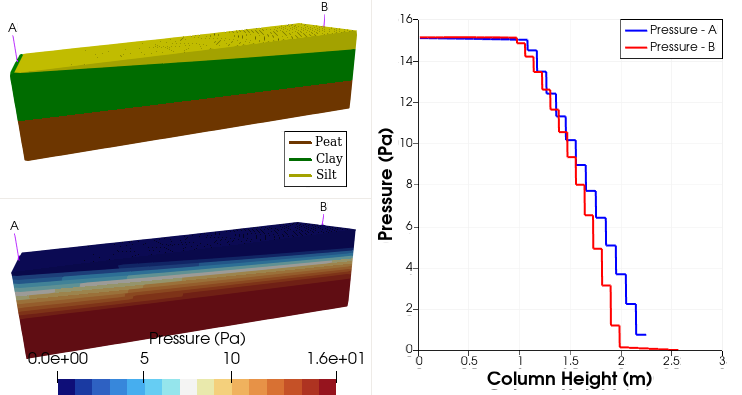

Figure: Layer of materials, pressure field and pressure path of two column in the domain.

Due to the formulation of this module, the solution stored in the output files is defined on an undeformed mesh. To facilitate the visualization and interpretation of the results, the following section presents a few useful [ParaView](https://www.paraview.org/) operations for displaying the solution on the evolving geometry. Similar filters and post-processing tools are also available in [VisIt](https://visit-dav.github.io/visit-website/index.html), although the workflow and terminology may differ between the two visualization platforms.

- **Find Data** – A useful tool for selecting or excluding specific regions of the domain based on the values of a selected field. This filter allows you to identify and isolate subsets of the dataset that satisfy user-defined criteria, making it easier to inspect and analyze particular features of the solution. This filter is especially useful for removing the  initial configuration from the visualization or for separating the domain into individual layers of material.

## 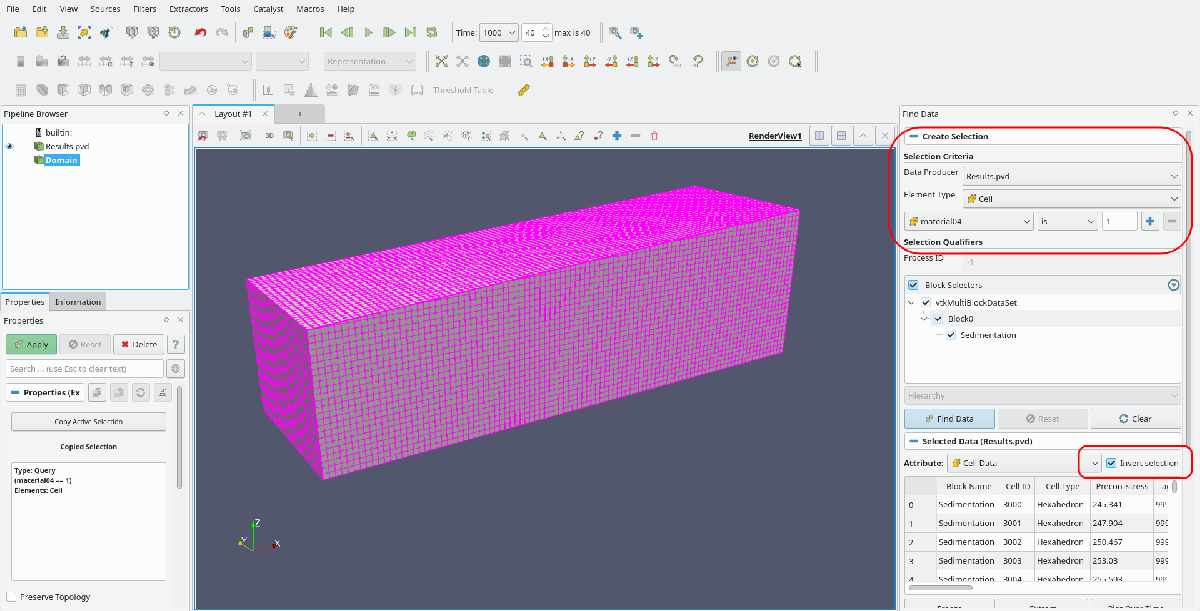

Figure: Removing the  initial configuration. First, select the material corresponding to the base, then invert the selection. This excludes the base from the visualization, leaving only the evolving portion of the domain.

## 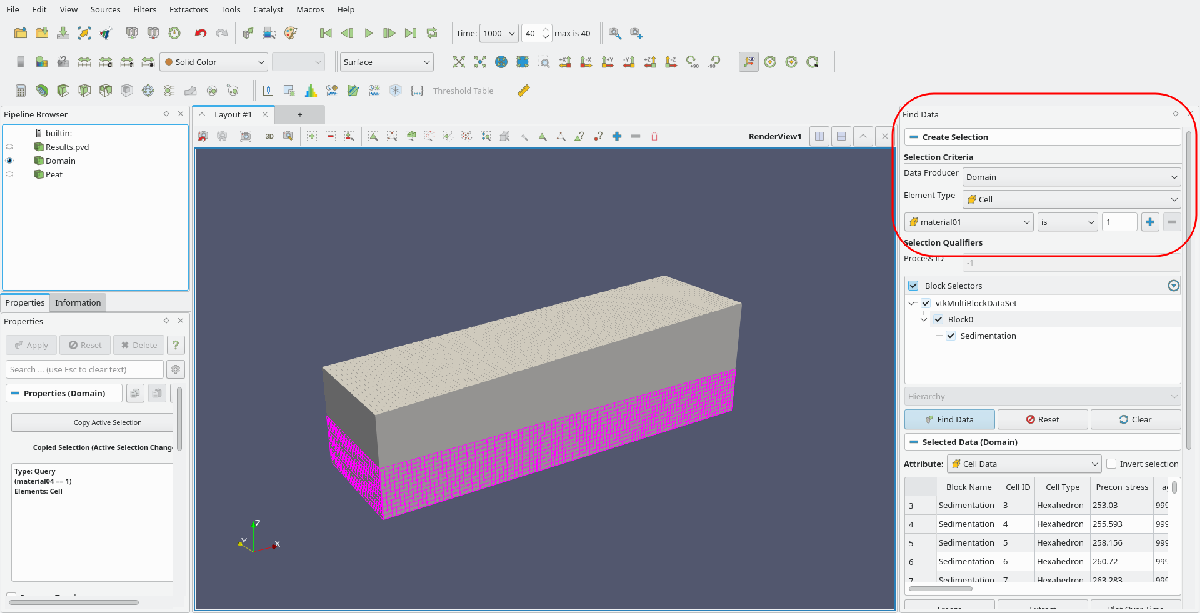

Figure: Selecting the peat in the domain.

- **Warp By Scalar** – Use this filter to visualize the deformation of the mesh by displacing its nodes according to the values of a nodal scalar field. For sedimentation simulations, select the **compaction** field and set the displacement direction to the **z**-axis.

## 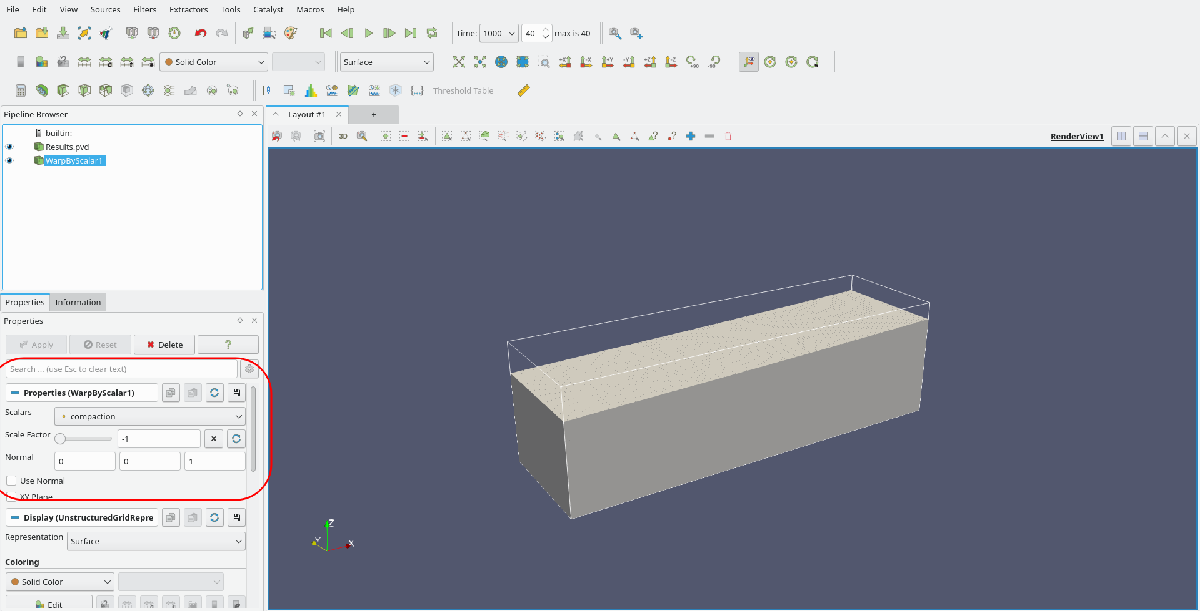

Figure: Mesh deformed by using this command. 

**Note:** The `compaction` field is stored as a positive quantity. To obtain the correct downward deformation, either set the **Scale Factor** to **-1** or specify the **Normal** direction as **(0, 0, -1)**.

- **Plot Over Line** – This filter extracts and displays the values of selected fields along a user-defined line in the dataset. By specifying the start and end points of the line, ParaView samples the solution along this path and generates a one-dimensional profile of the selected variables.This filter is useful for analyzing the variation of stress, strain or other quantities along a specific direction.

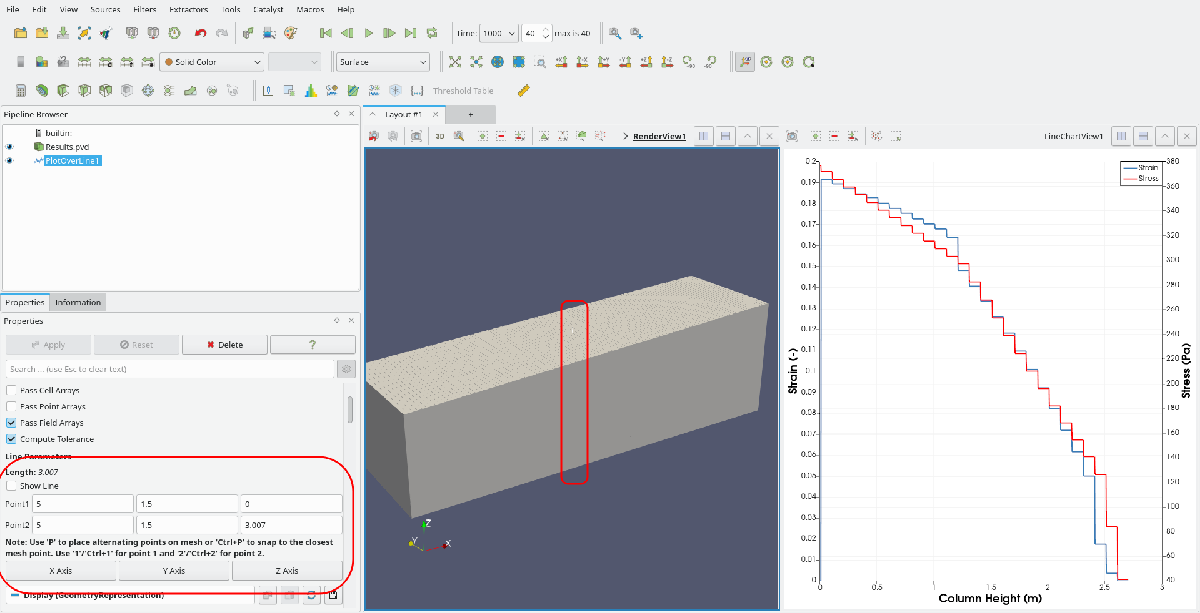

Figure: Definition of the sampling path. Select the starting and ending points of the line along which the data will be extracted using the **Plot Over Line** filter.

- **Plot Selection Over Time** – This filter extracts and displays the temporal evolution of selected data points or regions from a dataset. After defining a selection of interest, ParaView tracks the values of the selected variables over all available time steps and generates a time history plot.

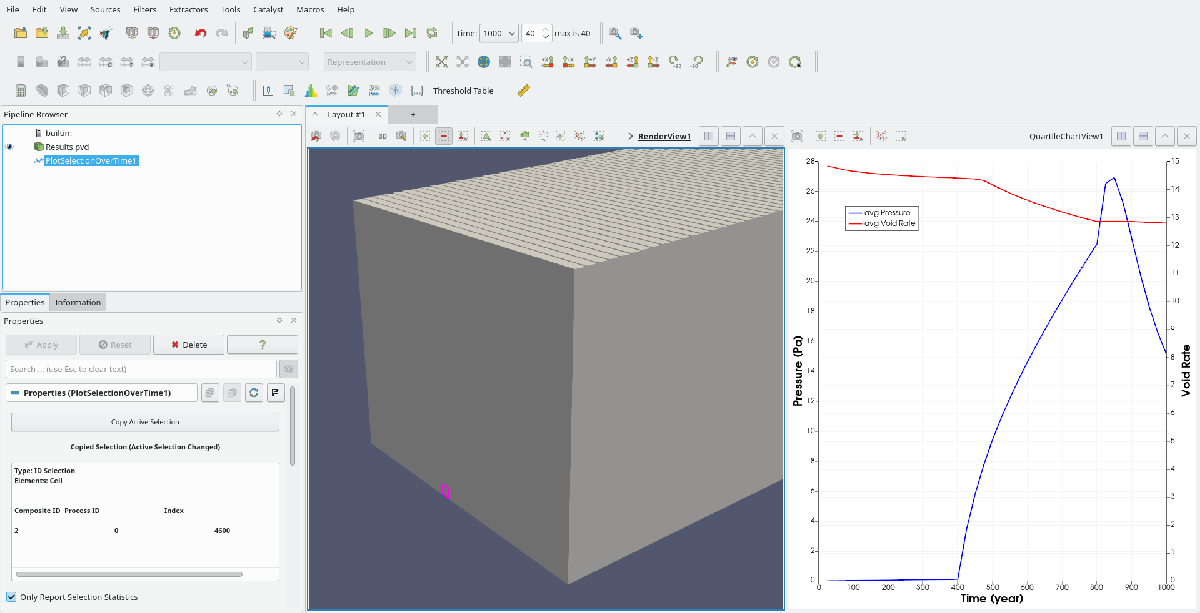

Figure: Definition of the selected region. Choose the points or region of interest that will be tracked over time.

- **Calculator** – This filter allows the creation of new data fields by applying mathematical expressions to existing variables in the dataset. It can be used to perform operations on scalar and vector fields, combine different variables, or compute derived quantities directly within ParaView.

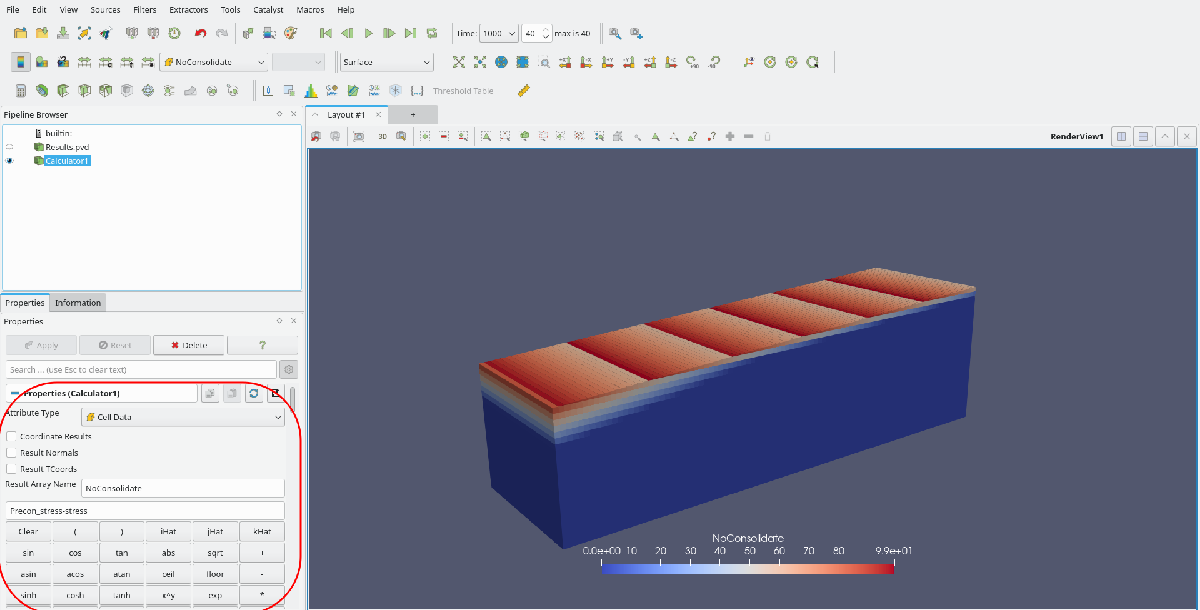

Figure: Example of the use of the **Calculator** filter. In this case, the filter is applied to identify regions where the stress level has not yet reached the preconsolidation value. The calculation is performed by evaluating the difference between the `Precon_stress` and `stress` fields, allowing the regions that satisfy the selected criterion to be easily identified.

## References

*R., Zoccarato, & Teatini, P. (2017). Numerical simulations of Holocene salt-marsh dynamics under the hypothesis of large soil deformations. Advances in Water Resources, 110, 107-119. *[*https:/doi.org/10.1016/j.advwatres.2017.10.006*](https://doi.org/10.1016/j.advwatres.2017.10.006)

*Xotta, R., Zoccarato, C., Minderhoud, P. S. J., & Teatini, P. (2022). Modeling the role of compaction in the three-dimensional evolution of depositional environments. Journal of Geophysical Research: Earth Surface, 127, e2022JF006590. *[*https://doi.org/10.1029/2022JF006590*](https://doi.org/10.1029/2022JF006590)

*Knut-Andreas Lie. An Introduction to Reservoir Simulation Using MATLAB/GNU Octave: User Guide for the MATLAB Reservoir Simulation Toolbox (MRST). Cambridge University Press, 2019*

*Varela, Jhabriel. Implementation of an MPFA/MPSA-FV solver for the unsaturated flow in deformable porous media. 2018.*